# Cat Scanning

*ECE367 Problem Set 4 Question 4.6*

*Aman Bhargava -- 1005189733*

## Tasks

- [x] Import the scanImage.p function.

- [x] Estimate `A` with the appropriate methods described in the text.

- [x] Show `A` using `imshow(A, [])` and include a scaled-down version in answers.

- [x] Use the reconstructed `A` matrix to determine the original of a 50x50 scanned image $M_{un}$ that is the result of `scanimage() `without passing input to the function.

- [x] Will result in an underdetermined degenerate system of equations. Plot the $r$ singular values $\sigma_i$ of $A$ versus their index and visually inspect the plot to choose a minimum for the non-zero singular values.

- [x] Use this in the Moore-Penrose pseudo-inverse to calculate the original of $M_{un}$

## Answers to Questions

As seen below: The hidden message is "WINTER IS COMING"

The chosen number of singular values was 1400.

% Defining some constants
h = 50;
w = 50;

n = h*w;
m = 1950; % Size of the output of scanImage(M)


% Generating A matrix

A = zeros(m,m);
inp = 0;
for i = 1:n
    inp = zeros(h,w);
    inp(i) = 1;
    A(:,i) = scanImage(inp);
end


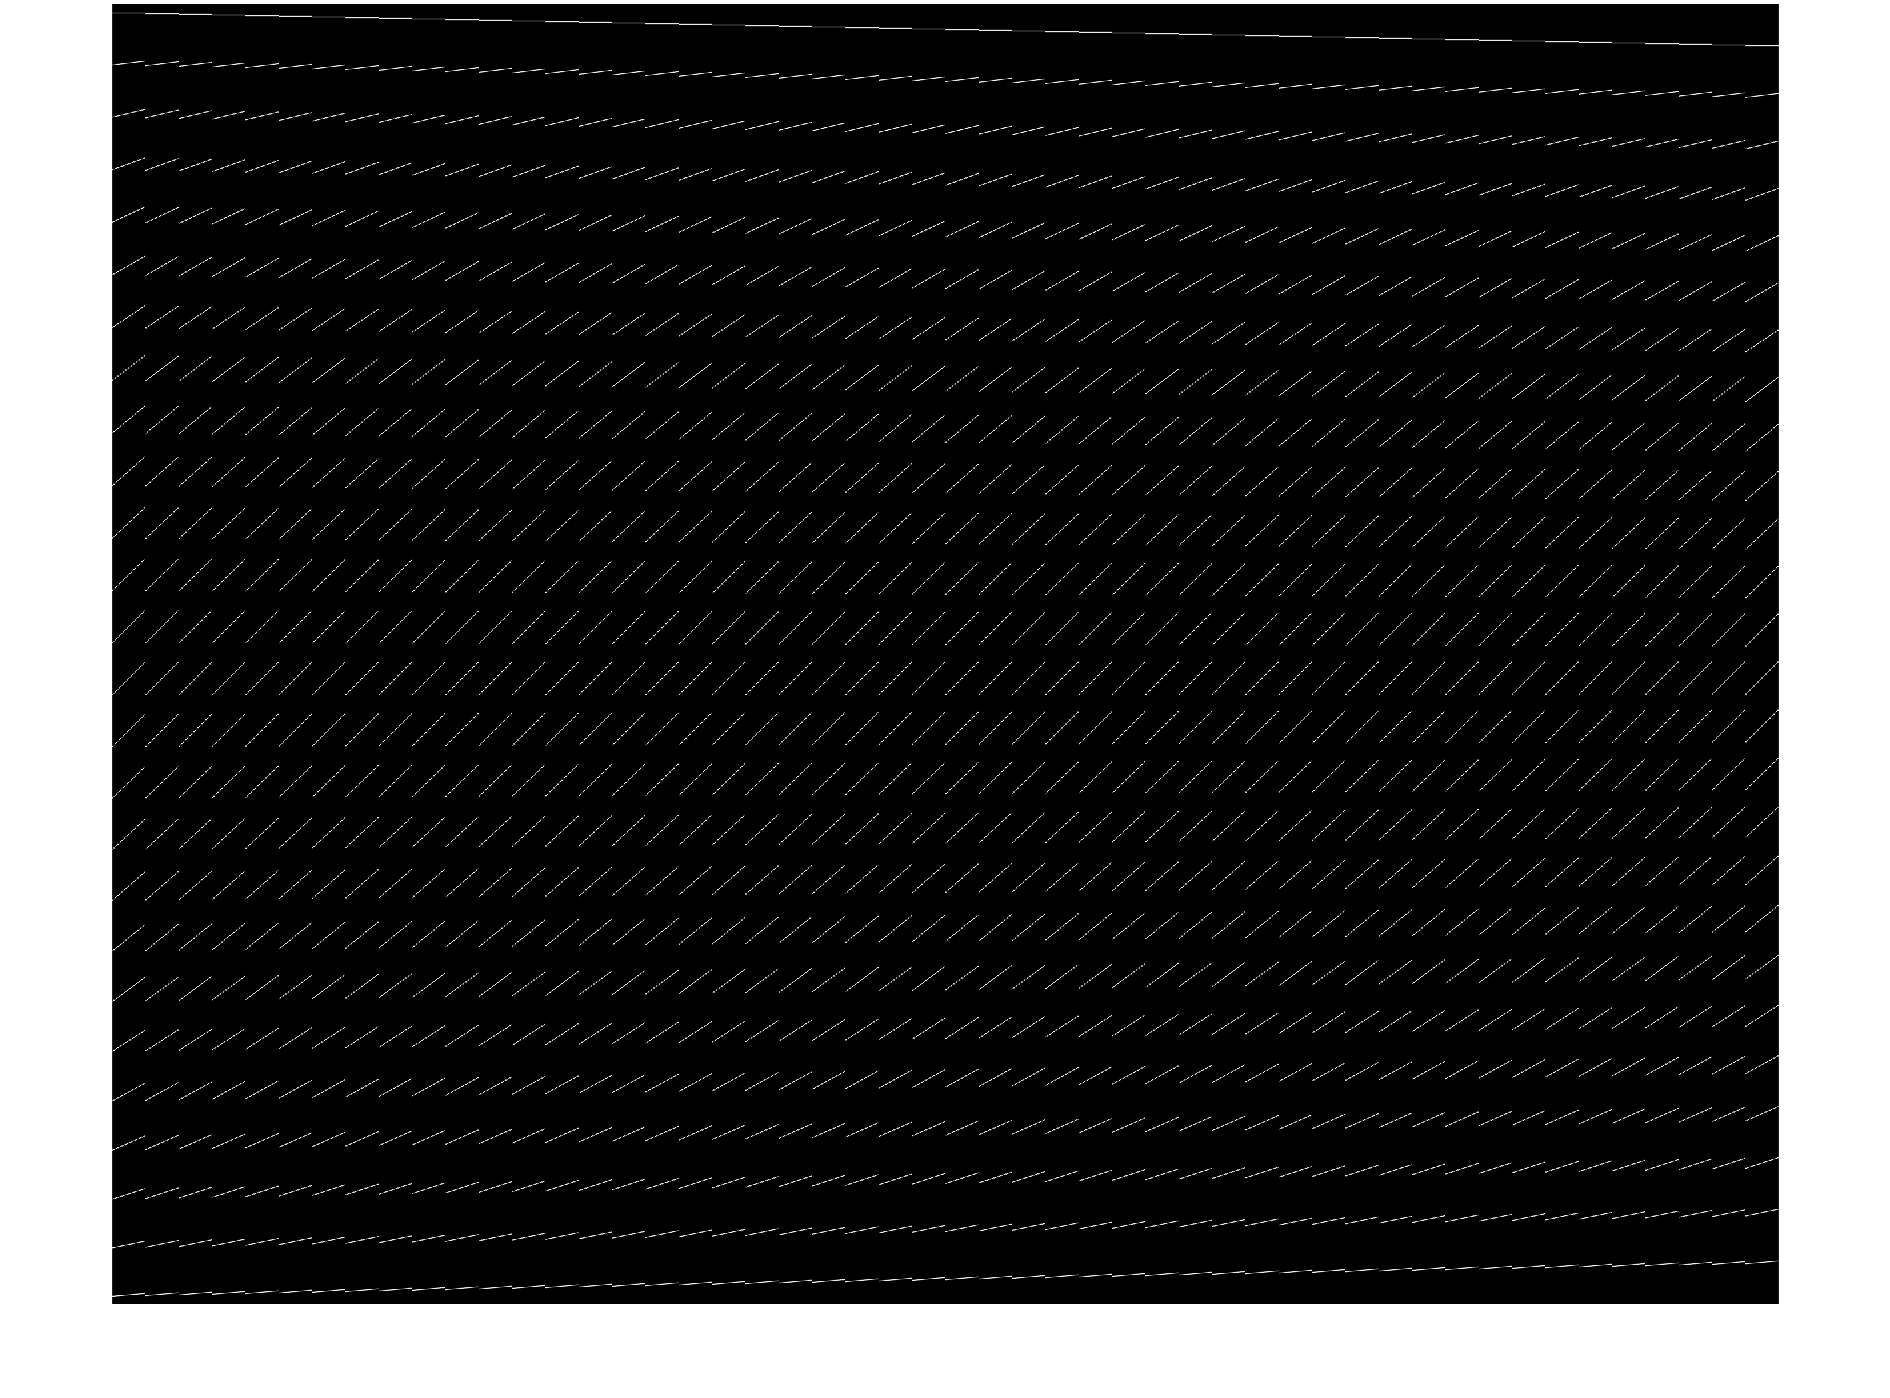

% Showing the image
imshow(A, [])

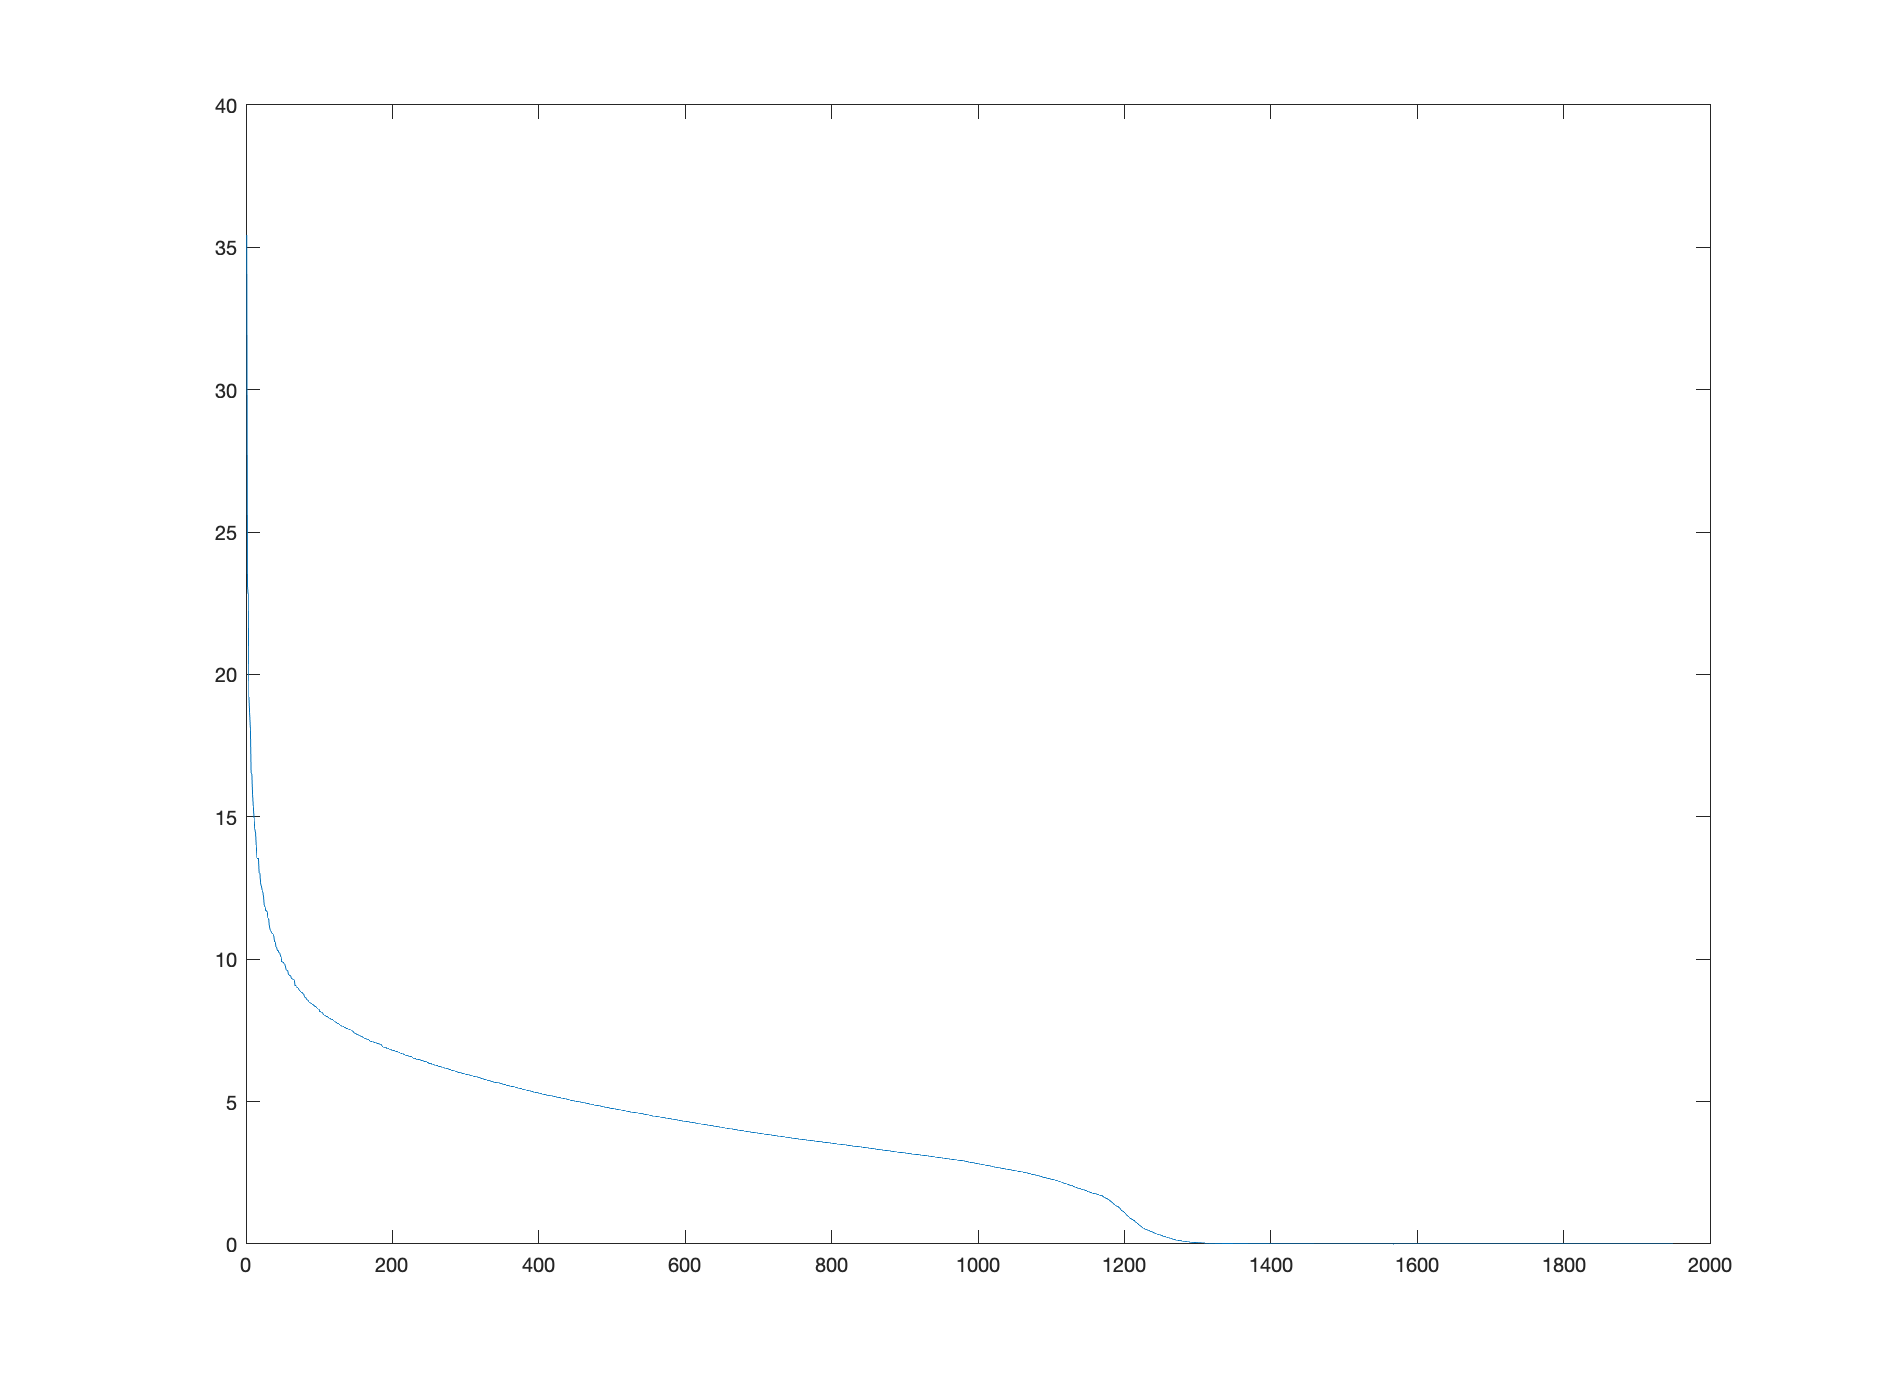

% Finding SVD of A:
[U,S,V] = svd(A,'econ');
sigmas = diag(S);
plot(sigmas);

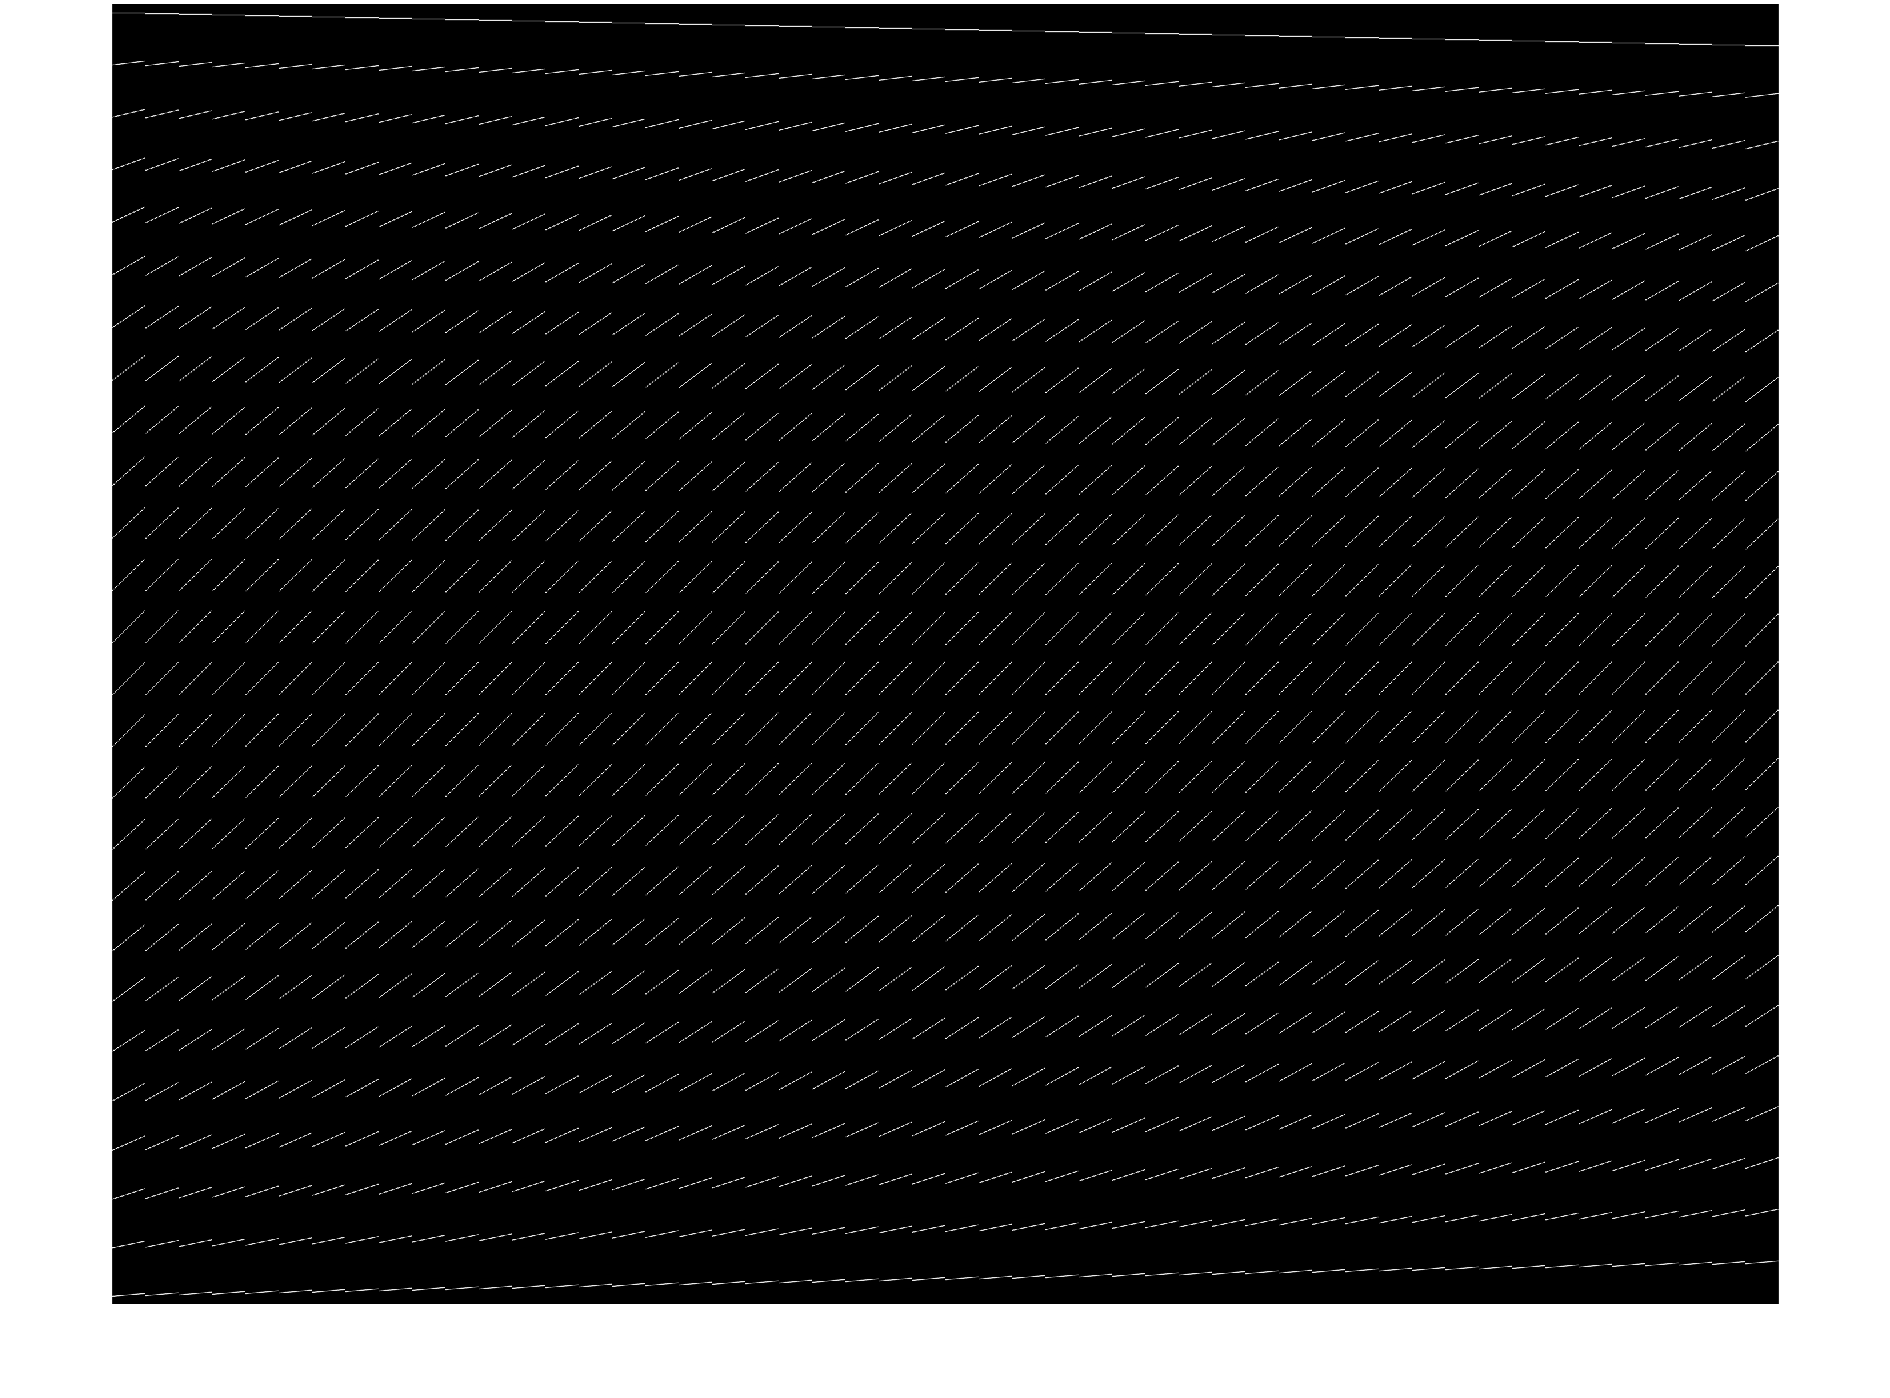

% Trimming SVD to eliminate all singular values after 1400
max_ind = 1400;
U = U(:,1:max_ind);
S = S(1:max_ind,1:max_ind);
V = V(:,1:max_ind);

A_reconstructed = U*S*transpose(V);
imshow(A_reconstructed, []); % Showing the reconstructed (trimmed) version

                             % as a sanity check.

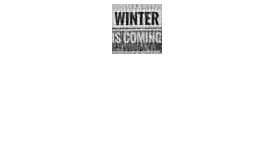

A_inv = V*inv(S)*transpose(U);
M_un = A_inv*scanImage();
imshow(reshape(M_un, [50,50]), []);